## PLS plots

d = SessManager.load_special('Mouse2022');
alpha = 0.02;

[X, ks] = d.get_dataset;
X_shuf = shuffle(X, ks);
X_z = zscore(X);
X_shuf_z = zscore(X_shuf);
[XS, stats, origin] =...
    Utils.pls_short(X_z, [ceil(ks/2), mod(ks,2)]);
XS_s = (X_shuf_z - mean(X_shuf_z)) * stats.W;
origin_s = -mean(X_shuf_z) * stats.W;

Using one session from Mouse2022, showing real data:

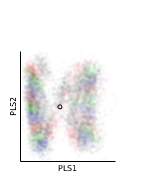

figure;
scatter(XS(:,1), XS(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin(1), origin(2), 10, 'k');
xlabel PLS1
ylabel PLS2
axis equal; 
axis tight;
xl_ = xlim;
yl_ = ylim;
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);

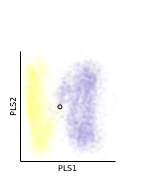

figure;
scatter(XS(:,1), XS(:,2), 8,...
    mod(ks,2),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin(1), origin(2), 10, 'k');
xlabel PLS1
ylabel PLS2
axis equal; 
axis tight;
xl_ = xlim;
yl_ = ylim;
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);

And shuffled data:

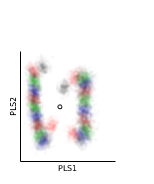

figure;
scatter(XS_s(:,1), XS_s(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_s(1), origin_s(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);

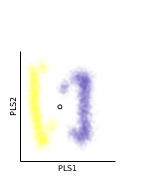

figure;
scatter(XS_s(:,1), XS_s(:,2), 8,...
    mod(ks,2),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_s(1), origin_s(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);